[I, map] = imread('C:\dev\biomedeng\Associated Files\Chapter 14\bonemarr.tif')

I = 238×270 uint8 matrix
   214   220   223   217   218   219   214   218   206   207   203   195   186   173   138   126   111   104    82    66    44    35    33    37    55    65    71    71    80    81    98   114   121   114   120   113   118    92    75    73    80   125   142   140   142   160   169   180   186   193
   218   219   231   227   227   224   219   220   213   213   204   200   195   187   159   130   107   100    77    65    47    39    32    36    57    78    84    76    77    80    98   102   116   106   106   102   102    80    67    66    76   116   136   138   135   145   142   156   175   194
   219   224   233   231   232   223   222   224   216   215   209   204   199   190   175   142   106    95    69    58    48    47    50    54    77   100    88    72    64    61    77    91   109   100    89    75    82    80    69    70    86   119   137   137   129   126   124   140   153   185
   222   224   237   233   233   223   225   226   219   215   212   207


map =

     []




I_d = im2double(I)

I_d =     0.8392    0.8627    0.8745    0.8510    0.8549    0.8588    0.8392    0.8549    0.8078    0.8118    0.7961    0.7647    0.7294    0.6784    0.5412    0.4941    0.4353    0.4078    0.3216    0.2588    0.1725    0.1373    0.1294    0.1451    0.2157    0.2549    0.2784    0.2784    0.3137    0.3176    0.3843    0.4471    0.4745    0.4471    0.4706    0.4431    0.4627    0.3608    0.2941    0.2863    0.3137    0.4902    0.5569    0.5490    0.5569    0.6275    0.6627    0.7059    0.7294    0.7569
    0.8549    0.8588    0.9059    0.8902    0.8902    0.8784    0.8588    0.8627    0.8353    0.8353    0.8000    0.7843    0.7647    0.7333    0.6235    0.5098    0.4196    0.3922    0.3020    0.2549    0.1843    0.1529    0.1255    0.1412    0.2235    0.3059    0.3294    0.2980    0.3020    0.3137    0.3843    0.4000    0.4549    0.4157    0.4157    0.4000    0.4000    0.3137    0.2627    0.2588    0.2980    0.4549    0.5333    0.5412    0.5294    0.5686    0.5569    0.6118    0.6863   


t1 = graythresh(I_d)

t1 = 0.6000

bw1 = im2bw(I, t1)

bw1 = 238×270 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


I_t = I_d > 0.7

I_t = 238×270 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

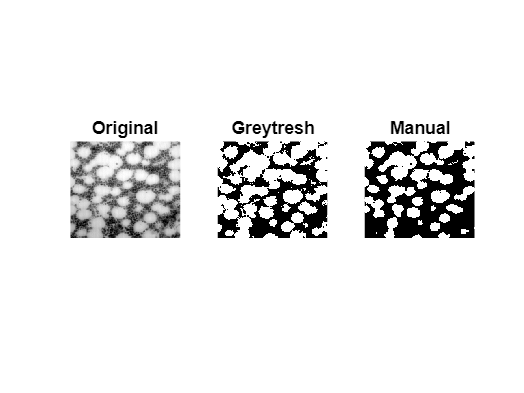


subplot(1, 3, 1)
imshow(I)
title('Original')

subplot(1, 3, 2)
imshow(bw1)
title('Greytresh')

subplot(1,3, 3)
imshow(I_t)
title('Manual')